For two wavelength, denoted the nxn super-pixel as vector with index $p=p_x+np_y$. Then the superposition of diffracted wave with wavelength w, from all pixels in this super-pixel is:


$$u(w)=\sum_{p_x=1}^n\sum_{p_x=1}^n
sp(p_x,p_y)exp(ik(p_xda+p_ydna)/f)\\
=\sum_{p=1}^{n^2}sp(p)\phi(p), \\\phi(p)=exp(i2\pi(w_0/w)p/n^2)$$


For a selected w0, calculate the correlatin matrix of phi

w=[0.65,0.445];
w0=1.3;
Npx=7;
phi=zeros(4,Npx^2);
p=0:Npx^2-1;
for iw=1:2
    phi((iw-1)*2+1,:)=cos(2*pi*(w0/w(iw))/Npx^2*p);
    phi((iw-1)*2+2,:)=sin(2*pi*(w0/w(iw))/Npx^2*p);
end
disp(corrcoef(phi'))

    1.0000   -0.0000   -0.0951    0.0338
   -0.0000    1.0000   -0.0171   -0.0665
   -0.0951   -0.0171    1.0000    0.0208
    0.0338   -0.0665    0.0208    1.0000



Also, to avoid frequency aliasing, we must have $(w/w_0)n>2$

disp(Npx*(w./w0))

    3.5000    2.3962



Searching proper parameters:

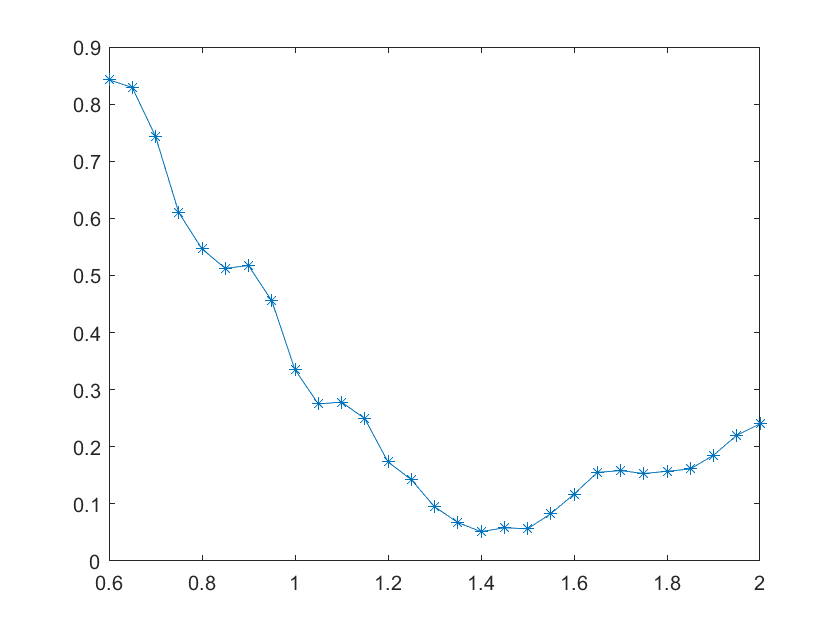

w=[0.65,0.445];
w0_list=0.6:0.05:2;
C=zeros(1,length(w0_list));
for indw=1:length(w0_list)
w0=w0_list(indw);
Npx=7;
phi=zeros(4,Npx^2);
p=0:Npx^2-1;
for iw=1:2
    phi((iw-1)*2+1,:)=cos(2*pi*(w0/w(iw))/Npx^2*p);
    phi((iw-1)*2+2,:)=sin(2*pi*(w0/w(iw))/Npx^2*p);
end
C(indw)=max(max(abs(corrcoef(phi')-diag(ones(1,2*length(w))))));
end
plot(w0_list,C,'-*')